# 【MATLAB】Table データを爆速で整理する関数を実装しよう

## はじめに

東京農工大学 MATLAB Student Ambassador の松本です．

MATLAB の table は，実験条件と結果をまとめて保存するのに適したデータ型です． 本記事では，筆者が普段使っている**table を効率的に整理するための関数**を紹介し， またその仕組みを解説します．

## 例：多項式によるデータのフィッティング

例として，多項式フィッティングの結果をまとめた `table` を使います（関数 `dummyData` は記事末尾に記載しています）．

この例は `train = true` のデータを次数 `N = 1, 2, ..., 10` の多項式でフィッティングした結果です．次数 `N` が小さすぎると十分にフィッティングできず， 反対に次数が大きすぎると train データに過適合しているようです．

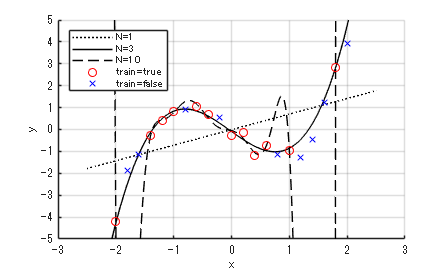

T = dummyData(); 

この様子を定量的に確認するために，`train = true` と `train = false` のそれぞれについて， 次数 `N` と予測誤差の平均値の関係をプロットしてみましょう．テーブル `T` の中身は次のようになっています．

disp(T)

     x       y_true     y_predict       error       train    N 
    ____    ________    __________    __________    _____    __

      -2     -4.1947         -1.43        2.7647    true      1
    -1.8     -1.8777       -1.2877       0.58996    false     1
    -1.6     -1.1235       -1.1454      0.021895    false     1
    -1.4    -0.27688       -1.0032       0.72628    true      1
    -1.2     0.41833       -0.8609        1.2792    true      1
      -1      0.8282      -0.71864        1.5468    true      1
    -0.8      0.9204      -0.57638        1.4968    false     1
    -0.6      1.0375      -0.43412        1.4716    true      1
    -0.4     0.67694      -0.29185       0.96879    true      1
    -0.2     0.56793      -0.14959       0.71752    false     1
       0    -0.25557    -0.0073262       0.24824    true      1
     0.2     -0.1519       0.13494       0.28684    true      1
     0.4     -1.1888        0.2772         1.466    true      1
     0.6    -0.72124       0.41946     

本記事で実装する `reduceTableByAxes` 関数を使うと，`N` と `train` の条件ごとの`error`の平均値（`@mean`）を， **3 行のコード**（＋見栄えを整えるための数行）で可視化できます．

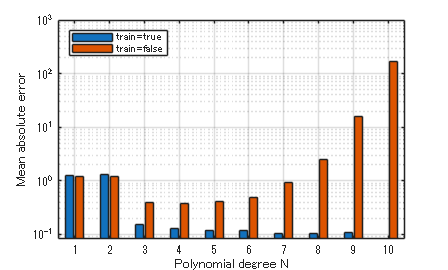

[averageError, axisValues] = reduceTableByAxes(T, ["N", "train"], "error", @mean);
bar(axisValues.N, averageError)
legend("train=" + string(axisValues.train), Location="northwest")

% 以下は見栄え調整
yscale("log")
xlabel("Polynomial degree N")
ylabel("Mean absolute error")
grid on

## 本記事の流れ

本記事では以下の 3 つの関数を順に実装＆解説していきます．

- `filterTable`：特定の条件を満たす行だけを取り出す

- `splitTableByAxes`：条件の組み合わせごとにデータを分ける

- `reduceTableByAxes`：分けたデータのそれぞれに対して平均値などを算出する

## 特定の条件を満たす行だけ取り出す

`N = 3` かつ test データ，すなわち `train == false` の行だけを取り出す処理は次のようなコードで書けます．

idx = T.N == 3 & T.train == false; % 条件を満たす要素が true の配列
Tfilt = T(idx, :);
disp(Tfilt)

     x       y_true     y_predict     error      train    N
    ____    ________    _________    ________    _____    _

    -1.8     -1.8777     -2.4668      0.58917    false    3
    -1.6     -1.1235     -1.1061     0.017482    false    3
    -0.8      0.9204     0.93454     0.014148    false    3
    -0.2     0.56793     0.27946      0.28847    false    3
     0.8     -1.1608     -1.0122      0.14865    false    3
     1.2     -1.2616    -0.44289      0.81873    false    3
     1.4    -0.43702     0.27261      0.70963    false    3
     1.6      1.2486      1.3414     0.092848    false    3
       2      3.9175       4.737      0.81955    false    3



この程度なら直接書いてもそれほど苦ではありませんが，条件が増えるたびに `T.変数名 == 値` を追加するのは地味に面倒です．

この問題を解決するために，変数名と値を順番に並べて指定できる `filterTable` を実装しましょう．

Tfilt = filterTable(T, "N", 3, "train", false);

### `filterTable`** の完成版**

function [Tfilt, idx] = filterTable(T, filterVar, filterValue)
arguments
    T table
end
arguments (Repeating) % 繰り返し引数
    filterVar (1,1) string % 変数名なので 1x1 の文字列であるべき
    filterValue
end

% 条件を満たす行の検索
idx = true(height(T), 1);
for k = 1:numel(filterVar)
    idx = idx & ismember(T.(filterVar{k}), filterValue{k});
end

% 条件を満たす行の抽出
Tfilt = T(idx, :);
end

### 解説

#### `arguments (Repeating)` で条件を繰り返し受け取る

`filterTable` では，`"N", 3` や `"train", false` のような「変数名と値の組」を，必要な数だけ受け取る必要があります． このような入力には，`arguments (Repeating)` が使えます．

繰り返し部分の引数は cell 配列として扱われます．例えば，

の場合， 第2引数以降の繰り返し部分は以下のように格納されます．

#### **条件を論理インデックスへ追加**

続いて，各条件を満たす行を示す論理インデックスを用意し，行を抽出します． まず全要素が `true` の配列を用意し，次いで各条件を満たす行との and を取っています．

`補足``：T.(filterVar{k})` は，文字列 `filterVar{k}` に対応する変数にアクセスします．例えば `filterVar{k}` が `"N"` なら，`T.N` と同じ意味になります．

`補足``：`比較には `==` ではなく `ismember` を使うことで，複数の値の OR 検索を可能にします．例えば以下の例では，`N` が2，3，4のいずれかであり，かつ `train` が false の行が抽出されます．

## 条件の組み合わせごとにテーブルを分ける

続いて，条件の組み合わせをごとにテーブルを分けたセル配列を作ります．冒頭の例の場合，1次元目を `N`，2次元目を `train` とした条件のグリッドを作り，各要素に条件を満たす部分を格納したいわけです．

%           train = false                        train = true
Tgroups = { filterTable(T,"N",1,"train",false),  filterTable(T,"N",1,"train",true),  % N = 1
            filterTable(T,"N",2,"train",false),  filterTable(T,"N",2,"train",true),  % N = 2
            ...
            filterTable(T,"N",10,"train",false), filterTable(T,"N",10,"train",true), % N = 10
            };

このような配列を簡単に作成するために， 軸（ここでは `N` と `train`）を指定するだけでテーブルのグループ分けを実行する `splitTableByAxes` を実装しましょう．

[Tgroups, axisValues] = splitTableByAxes(T, ["N", "train"]);

なお，axisValues は構造体で，各軸の値が格納されています．上記の例の場合は以下のようになります．

### `splitTableByAxes` の完成版

function [Tgroups, axisValues] = splitTableByAxes(T, axisVars)
arguments
    T        table
    axisVars (1,:) string
end

% 各軸に含まれる値を取得
numAxes       = numel(axisVars);
axisSizes     = zeros(1, numAxes);
axisValueList = cell(1, numAxes);
axisValues    = struct;

for axisIdx = 1:numAxes
    axisVar = axisVars(axisIdx);
    values  = unique(T.(axisVar), "stable");

    axisValues.(axisVar)   = values;
    axisValueList{axisIdx} = values;
    axisSizes(axisIdx)     = numel(values);
end

% 条件の全組み合わせを作成
axisCombinations = combinations(axisValueList{:});
axisCombinations.Properties.VariableNames = cellstr(axisVars);

% 各条件を満たすテーブルを抽出
Tgroups = cell(height(axisCombinations), 1);
for combinationIdx = 1:height(axisCombinations)
    filterArgs = [
        num2cell(axisVars)
        table2cell(axisCombinations(combinationIdx, :))
        ];
    Tgroups{combinationIdx} = ...
        filterTable(T, filterArgs{:});
end

% セル配列の各次元を軸に対応させる
Tgroups = reshape(Tgroups, [fliplr(axisSizes), 1]);      % 多次元配列に変形
Tgroups = permute(Tgroups, [numAxes:-1:1, numAxes + 1]); % 軸の順番を逆転
end

### 解説

#### `for` **ループを用いた簡易的な実装**

一見すると少し複雑なので，まずは軸を `N` と `train` の2つに限定した，素朴な実装から考えてみます． `N` と `train` に含まれる値を `unique` 関数を使って洗い出し，先ほど作った `filterTable` を呼び出せばよいので，次のように書けます．

nValues     = unique(T.N, "stable");     % [1,2,3,4,5,6,7,8,9,10]
trainValues = unique(T.train, "stable"); % [false, true]

Tgroups = cell(numel(nValues), numel(trainValues));
for nIdx = 1:numel(nValues)
    for trainIdx = 1:numel(trainValues)
        Tgroups{nIdx, trainIdx} = filterTable(T, "N", nValues(nIdx), "train", trainValues(trainIdx));
    end
end

ただし，軸が増えるたびに `for` ループも増やさなければなりません． `splitTableByAxes` では，この「全組み合わせを列挙して `filterTable` を呼ぶ」という処理を，軸の数によらず同じコードで実行できるようにしています．

#### **各軸に含まれる値を集める**

まず，`axisVars` で指定された各変数について，テーブル内に存在する値を `unique` で取得し，これを `axisValueList` に格納します．

`axisSizes` には，各軸に含まれる値の個数を保存します．これは，最後に cell 配列を多次元配列へ変形するときに使用します． `splitTableByAxes(T, ["N", "train"]);` の場合，`axisSizes = [10, 2]` となります．出力用の `axisValues` もこの段階で作成します．

#### `combinations` **で条件の全組み合わせを作る**

各軸の値が得られたので，次は全条件の組み合わせを列挙します．

`axisValueList{:}` を，組み合わせを列挙する `combinations` 関数に渡しています． `splitTableByAxes(T, ["N", "train"]);` の場合，結果は次のような table になります

各行が一つの条件に対応しています．二重 `for` ループで `nIdx` と `trainIdx` を動かしていた処理を，条件の一覧表として先に作っていると考えると分かりやすいでしょう．

#### **各条件について filterTable 関数を適用する**

次に，`axisCombinations` を一行ずつ取り出し，変数名とともにセル配列 `filterArgs` に格納します． その後，これを `filterTable` に入力して条件を満たす行を抽出します．

`補足``：N = 3`，`train = false` に対応する行では，`filterArgs` は次のようになります．

**補足**：MATLAB は配列を列優先で展開するため，`filterArgs{:}` は `"N", 3, "train", false` に対応します．したがって，以下の二つは等価になります．

#### **cell 配列の各次元を軸に対応させる**

この時点の `Tgroups` は，組み合わせを縦に並べた cell 配列です． 最後に，1次元目が `axisVars(1)`，2次元目が `axisVars(2)`，という形になるように形を整えます．

`combinations` の出力では，後ろの軸ほど速く変化します．一方，MATLAB の `reshape` は1次元目から順番に要素を詰めます．そのため，まず `axisSizes` を反転した形に `reshape` し，その後 `permute` で次元の順番を戻しています．

### 条件の組み合わせごとに代表値を計算する

ここまでで，`N` と `train` の組み合わせごとにテーブルを分けることができました． 最後に，各条件ごとに `error` の平均を求めましょう．

`splitTableByAxes` によって得られる `Tgroups` はセル配列で，その各要素はテーブルです． したがって，for 文でその各要素を取り出し，その `tblij.error` の平均値を求めればOKです．

for i = 1:10
    for j = 1:2
        Tij = Tgroups{i,j};
        averageError(i,j) = mean(Tij.error);
    end
end

ただし，このようにセル配列の各要素に同じ操作を適用する操作は `cellfun` 関数を使えば より完結に書くことができます．上記の例の場合，二重の for 文部分を以下の2行に置き換えることができます．

fun = @(T) mean(T.error); % T を受け取って error の平均値を返す無名関数
averageError = cellfun(fun, Tgroups);

汎用性を高めるために，計算対象となる変数（ここでは `error`）と，代表値を計算する関数（ここでは `mean`）も 入力により指定できる，分割と関数適用をまとめて行う `reduceTableByAxes` を実装しましょう．

[averageError, axisValues] = reduceTableByAxes(T, ["N", "train"], "error", @mean);

これにより，「テーブル `T` を `N` と `train` の条件ごとに分け，その `error` の平均値を計算する」という操作を簡潔に実装できるようになります

## reduceTableByAxes の完成版

function [reducedValues, axisValues] = ...
    reduceTableByAxes(T, axisVars, valueVar, reduceFcn)
arguments
    T       table
    axisVars  (1,:) string
    valueVar  (1,1) string
    reduceFcn (1,1) function_handle
end

[Tgroups, axisValues] = splitTableByAxes(T, axisVars);

fun = @(T) reduceFcn(T.(valueVar));
reducedValues = cellfun(fun, Tgroups);
end

## まとめ

本記事では，table データを条件ごとに整理するための3つの関数を実装しました． `filterTable` では指定した条件を満たす行を抽出し，`splitTableByAxes` では複数の条件の組み合わせごとにテーブルを分割しました．さらに，`reduceTableByAxes` を使うことで，各グループに対して平均値などの代表値をまとめて計算できるようになりました．

これらの関数を組み合わせることで，条件の追加や変更のたびに論理インデックスや多重の `for` 文を書き直す必要がなくなり， テーブルデータの整理を効率化できるはずです！

function T = dummyData
rng(1)
x         = (-2:0.2:2)';
y_true    = x.^3 - 2 * x + 0.3 * randn(size(x));
train     = rand(size(x))<0.7;
test      = ~train;

x_train   = x(train);
y_train   = y_true(train);

x_test    = x(test);
y_test    = y_true(test);

fit1      = polyfit(x_train, y_train, 1);
fit3      = polyfit(x_train, y_train, 3);
fit10     = polyfit(x_train, y_train, 10);

figure; hold on;

fplot(@(x)polyval(fit1,x),[-2.5 2.5],"k:","DisplayName","N=1")
fplot(@(x)polyval(fit3,x),[-2.5 2.5],"k-","DisplayName","N=3")
fplot(@(x)polyval(fit10,x),[-2.5 2.5],"k--","DisplayName","N=10")

scatter(x_train,y_train,"ro","DisplayName","train=true")
scatter(x_test,y_test,"bx","DisplayName","train=false")

xlabel("x");
ylabel("y");

legend("Location","northwest");
ylim([-5 5]);
grid on;
T=table();
for n = 1:10
    y_predict = polyval(polyfit(x_train, y_train, n),x);
    error     = abs(y_true - y_predict);
    N         = repmat(n,numel(x),1);
    T         = [T; table(x,y_true,y_predict,error,train,N)];
end
hold off
end